### Testing shape generation

length = 5;
posn_square = [1; 3];
theta = pi/6; % Rads
resolution = 100; % Points per side
points_square = generate_square(length, posn_square, theta, resolution);

radius = 2;
posn_circle = [-1; -3];

points_circle = generate_circle(radius, posn_circle, resolution);

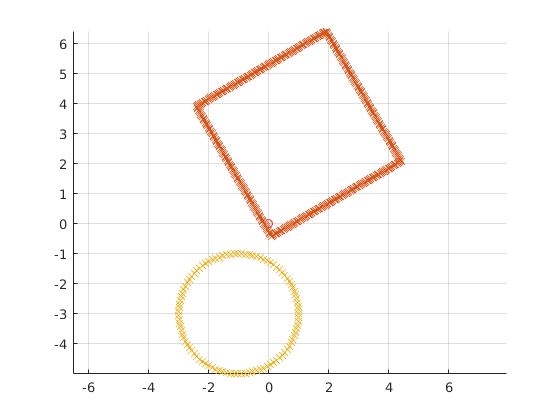

figure();
hold on

plot(0, 0, 'ro')

scatter(points_square(1, :), points_square(2, :), 'x')
scatter(points_circle(1, :), points_circle(2, :), 'x')

grid on
axis equal

function points_out = generate_square(length, position, theta, resolution)

% Create square points
edge_coords = length * linspace(-0.5, 0.5, resolution);
const_coords = length * 0.5*ones(size(edge_coords));

top_edge = [edge_coords; const_coords];
bottom_edge = [edge_coords; -const_coords];

left_edge = [-const_coords; edge_coords];
right_edge = [const_coords; edge_coords];

points_out = [top_edge, bottom_edge, left_edge, right_edge];

% Rotate square about center
rot_mat = [cos(theta) -sin(theta);
           sin(theta)  cos(theta)];

points_out = rot_mat*points_out;

% Translate square
points_out = [points_out; ones(1, size(points_out, 2))];
trans_mat = eye(3);
trans_mat(1:2, 3) = position;

points_out = trans_mat*points_out;

end

function points_out = generate_circle(radius, position, resolution)

thetas = linspace(0, 2*pi, resolution);

% Create circle points
points_out = [radius*cos(thetas);
          radius*sin(thetas);
          ones(size(thetas))];

% Translate circle
trans_mat = eye(3);
trans_mat(1:2, 3) = position;

points_out = trans_mat*points_out;

end